# SMART FITNESS TRACKER : DEMONSTRATION

## Introduction :-

This is a demonstration file explaining the idea and skeleton holding its foundation of working as a fitness tracker.

To Identify and Classify the usual *walking,running, stair climbing & sitting or standing *mode for an usual human being, we've done the the signal analysis of accelerometer and gps data that later on helps to find out the steps covered(if walking or running), flight of stairs, calories burnt etc.

### What we actually did :-

    Our activities generally have a pattern, and that too in the form of vibration. our usual walk, stair climbing and even the course of running has a special orientation in most cases and with each of the footsteps, there comes a slight change in that orientation, which if recorded through a sensor can be analysed and created a special connection between the vibration and the footsteps. And thus, we can find out what actually is the type of the activity the person doing and further by more analysis and calculation, we can find out the footstep count and other insights related to the health.

    And in this project, we actually tried to achieve that case where we capture & analyse the accelerometer & the gps data, do some calculations and find the steps covered and other things also.

###     The step counting process :

**After we got the data: **We after getting the data simply processed the acceleration along x,y and z axis to a single parameter by this formula, 

####                 
$$M = \sqrt{X^2 + Y^2 + Z^2}
$$


And finally plotted it as Acceleration Magnitude vs Data Samples graph which looked like this:

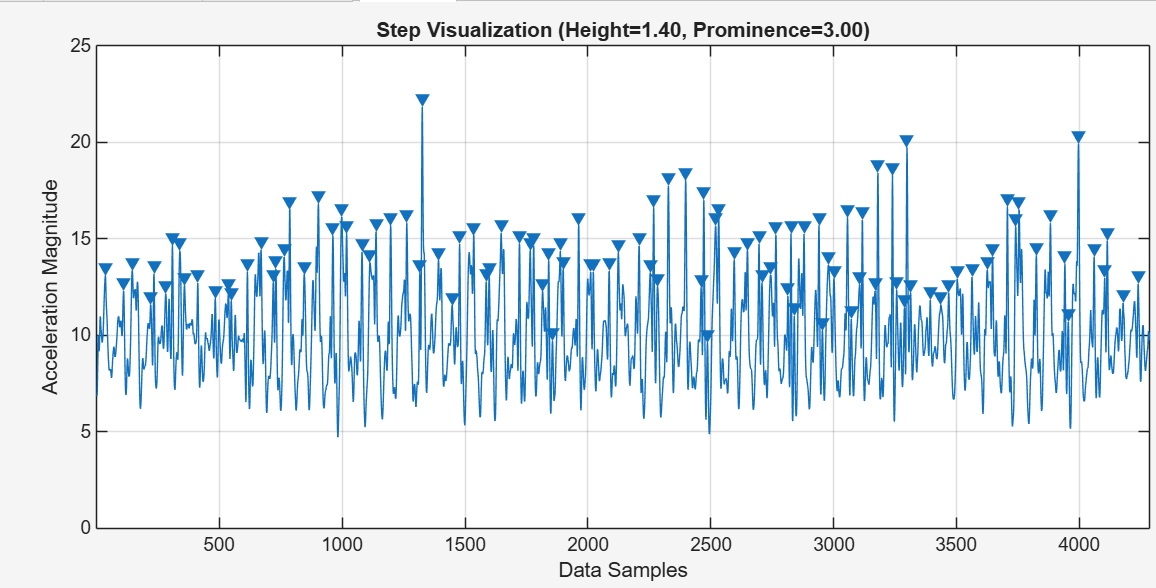

Now comes the crutial part, how to find out steps from the plot? Well here helps the concept of *"peak and prominence" . *Basically the acceleration magnitude changes when we make a step forward, and the peak is the main indicator in this case. And prominence tells us in which way the peak of the footstep is unique than the wave itself.

-     **Peak: **Is the highest value at a time the wave is approaching.

-     **Prominence: **Is the distinction or uniqueness of the peak compared to its close neighbouring sharp creases at a given sample and at a given time. This helps the most in seperating noises from the actual footstep.

###     The calculation of Distance covered :

The total distance was found by summing the length of each tiny segment of the path.

- **The Challenge**: A simple formula doesn't work because the Earth is curved.

- **The Solution**: We used the **Haversine formula**, which is the standard method for accurately calculating distance on a sphere.

- **The Process**: Our *calculateDistance()* function loops through the entire route, measures each small segment with the Haversine formula, and adds them all up to get the final, accurate total distance.

###     The Route Map :

After getting the positional data, its then divided into tiny chunks with individual latitude & longitude. Then we calculated the difference between consecutive chunks' latitude & longitude individually, obtaining a table of data that later is used to plot the movement of the person. A sample movement along the speed is shown below in the plot:

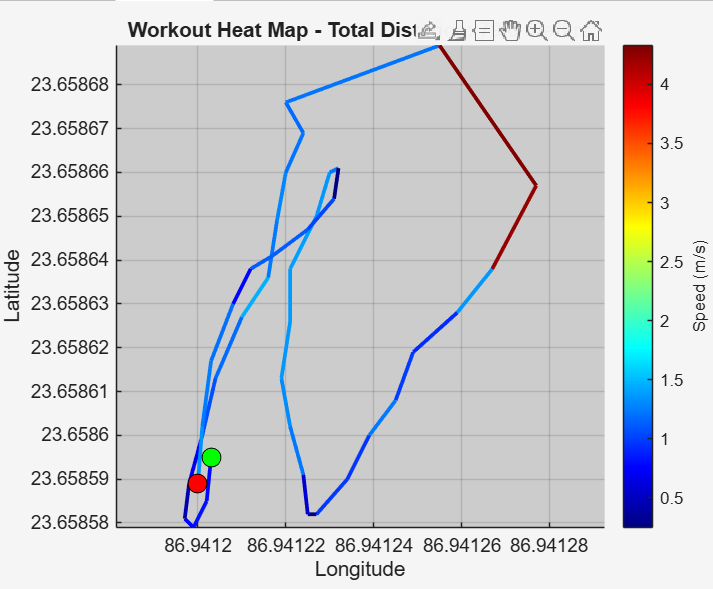

###     The calculation of the flight of stairs :

The number of flights climbed was determined by analyzing the altitude data from the phone's sensors.

- **The Standard**: A "flight climb" is counted for every **10 feet (3 meters) of continuous elevation gain**.

- **The Method**: Our countStairs() function intelligently analyzes the smoothed altitude data to find periods of sustained climbing.

- **The Logic**: It adds up the elevation gain during each climb. When a period of climbing ends (because the user leveled off or descended), the total gain from that single ascent is counted. For every 3 meters gained, one flight is awarded. This method correctly ignores minor hills and sensor noise.

###     The estimation of calories burnt :

The calorie burn was estimated using a standard scientific method based on the activity's intensity.

- **The Concept**: We use a measure called **Metabolic Equivalent of Task (METs)** to represent the intensity of an exercise. For example, running has a higher MET value than walking.

- **The Method**: A standard MET value is assigned based on the **activity type our model detected** ('walking', 'running', 'stairs', etc.).

- **The Formula**: The final calorie count is calculated using a standard formula that combines the activity's **MET value**, the user's **body weight**, and the total **duration** of the workout.

###     The 'fingerprint' thing :

Our model calculates a unique "fingerprint" for any activity by measuring two key features from the acceleration data: the **average magnitude** (overall intensity) and the **standard deviation** (the "shakiness"). Different activities like walking and running have distinct combinations of these two features, which allows our rule-based model to accurately classify the user's movement.

## The Ace Up The Sleeve :-

Our tracker's "brain" uses a data "fingerprint" (based on intensity and shakiness) to distinguish between activities. This section runs a diagnostic on all our collected data to visualize these fingerprints. This plot proves that our classification method is data-driven and accurate.

%classifier diagnostic
fprintf('Analyzing all data files to show activity clusters...\n');

Analyzing all data files to show activity clusters...


data_files = dir('*.mat');
fingerprint_table = table();

for i = 1:length(data_files)
    filename = data_files(i).name;
    load(filename);
    if exist('Acceleration', 'var') && ~isempty(Acceleration)
        [avg_mag, shakiness] = analyzeActivity(Acceleration);
        if contains(filename, 'walk', 'IgnoreCase', true), activity_type = "Walking";
        elseif contains(filename, 'run', 'IgnoreCase', true) || contains(filename, 'jog', 'IgnoreCase', true), activity_type = "Running";
        elseif contains(filename, 'stairs', 'IgnoreCase', true), activity_type = "Stairs";
        elseif contains(filename, 'sit', 'IgnoreCase', true), activity_type = "Sitting";
        else, activity_type = "Unknown";
        end
        fingerprint_table = [fingerprint_table; {activity_type, avg_mag, shakiness}];
    end
end

fingerprint_table.Properties.VariableNames = {'Activity', 'AvgMag', 'Shakiness'};
disp(fingerprint_table);

    Activity     AvgMag    Shakiness
    _________    ______    _________

    "Running"    9.8391     0.68686 



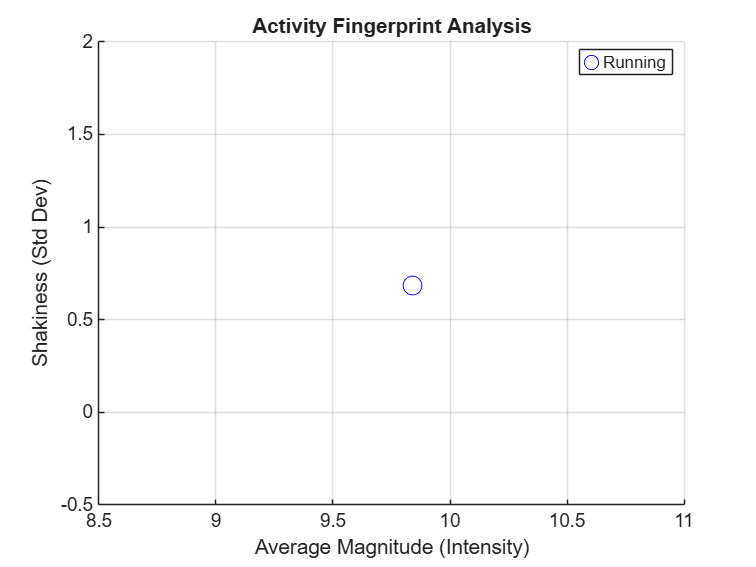

figure;
gscatter(fingerprint_table.AvgMag, fingerprint_table.Shakiness, fingerprint_table.Activity, 'brgkc', 'o', 10, 'on');
grid on;
xlabel('Average Magnitude (Intensity)');
ylabel('Shakiness (Std Dev)');
title('Activity Fingerprint Analysis');
legend('Location', 'best');

## Full Analysis of a Sample Workout :-

test_file = 'SJ_running.mat'; 
user_weight_kg = 70; %makiing up the person's profile
load(test_file);

if contains(test_file, 'Stairs', 'IgnoreCase', true), detected_mode = 'stairs';
elseif contains(test_file, 'run', 'IgnoreCase', true), detected_mode = 'running';
else, detected_mode = 'walking';
end
fprintf('\n Running Full Analysis on: %s \n', test_file);


 Running Full Analysis on: SJ_running.mat 


fprintf(' Mode set to: %s\n', detected_mode);

 Mode set to: running


## Final Results and Visuals :-

Here are the final calculated metrics and visualizations for the sample workout.

% calculation and result display
duration = calculateDuration(Acceleration);
[step_count, height, prom] = Steps_Count(Acceleration, detected_mode);
total_distance = calculateDistance(Position);
flight_climb = countStairs(Position);
[calories_burned, met] = calculateCalories(detected_mode, duration, user_weight_kg);

fprintf('\n Workout Summary\n');


 Workout Summary


fprintf('Duration: %d min, %.0f sec\n', floor(duration / 60), rem(duration, 60));

Duration: 0 min, 47 sec


fprintf('Steps: %d\n', step_count);

Steps: 25


fprintf('Distance: %.1f meters\n', total_distance);

Distance: 0.7 meters


fprintf('Flights Climbed: %d\n', flight_climb);

Flights Climbed: 0


fprintf('Calories Burned: %.1f kcal\n', calories_burned);

Calories Burned: 6.8 kcal


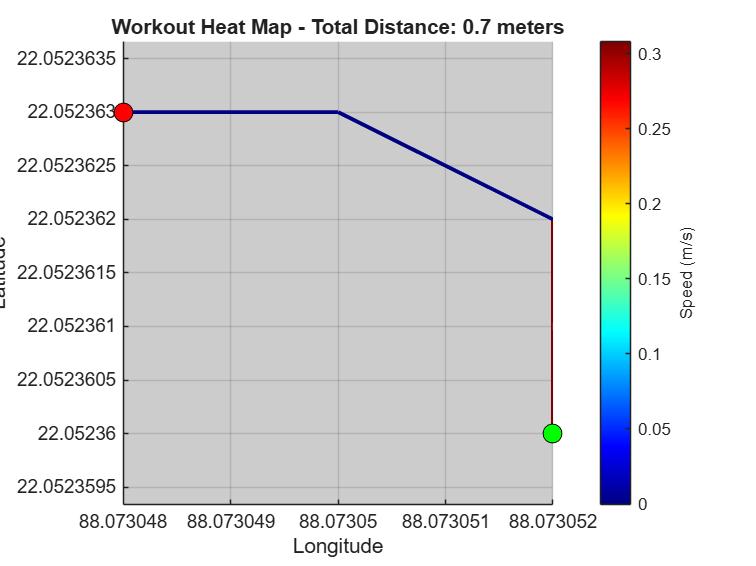

fprintf('\n');

% visualisation
plotRouteMap(Position, total_distance);

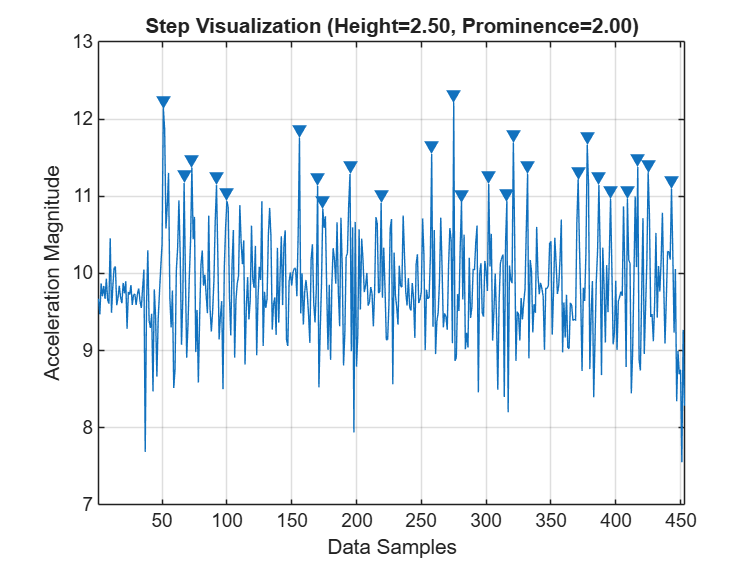

visualiseSteps(Acceleration, height, prom);

## Local Functions :-

Now its high time to provide the whole skeleton and the workings of this project, that is the collection of the functions used above.

function [avg_mag, shakiness] = analyzeActivity(accel_data)
    mag = sqrt(sum(accel_data{:,:}.^2, 2));
    
    avg_mag = mean(mag);
    shakiness = std(mag);
end



function total_seconds = calculateDuration(sensor_timetable)

    if ~istimetable(sensor_timetable) || height(sensor_timetable) < 2
        total_seconds = 0;
        return;
    end
    
    % time vector extraction from timestamp data
    time_vector = sensor_timetable.Timestamp;
    
    % time difference
    duration_object = time_vector(end) - time_vector(1);
    
    % to seconds
    total_seconds = seconds(duration_object);
end



function [step_count, peak_height, peak_prominence] = Steps_Count(accel_data, mode)
    if height(accel_data) < 2
        step_count = 0; peak_height = 0; peak_prominence = 0;
        return;
    end

    mag = sqrt(sum(accel_data{:,:}.^2, 2));

    if strcmp(mode, 'running')
        peak_height = 2.5;
        peak_prominence = 2.0;
        toProcess = mag;

    elseif strcmp(mode, 'stairs')
        peak_height = 2.0;
        peak_prominence = 1.5;
        toProcess = mag;

    elseif strcmp(mode, 'stabilized')
        peak_height = 0.05;
        peak_prominence = 0.1;
        if numel(mag) > 20
            toProcess = mag - movmean(mag, 20);
        else
            toProcess = mag;
        end

    else % 'walking' case
        peak_height = 1.5;
        peak_prominence = 0.8;
        toProcess = mag;
    end
    
    [pks, ~] = findpeaks(toProcess, 'MinPeakHeight', peak_height, 'MinPeakProminence', peak_prominence);
    step_count = numel(pks);
end



function dist_mtrs = calculateDistance(pos_data)
    if height(pos_data) < 2
        dist_mtrs = 0;
        return;
    end

    R = 6371e3; % earth's radius
    lat = deg2rad(pos_data.latitude);
    lon = deg2rad(pos_data.longitude);
    
    dLat = diff(lat);
    dLon = diff(lon);
    
    a = sin(dLat/2).^2 + cos(lat(1:end-1)) .* cos(lat(2:end)) .* sin(dLon/2).^2;
    c = 2 * atan2(sqrt(a), sqrt(1-a));
    
    dist_segment = R * c;
    dist_mtrs = sum(dist_segment);
end



function flight_climb = countStairs(position_data)

    if height(position_data) < 2 || ~ismember('altitude', position_data.Properties.VariableNames)
        flight_climb = 0;
        return;
    end


    altitude = position_data.altitude;
    
    % smoothening
    altd_smooth = smoothdata(altitude, 'gaussian', 10);
    
    min_altitude = min(altd_smooth);
    max_altitude = max(altd_smooth);
    
    total_ascent_meters = max_altitude - min_altitude;
    
    % ascent to flights. Standard: 3mtrs.
    meters_per_flight = 3; 
    
    % divide the total ascent by the height of one flight.
    flight_climb = floor(total_ascent_meters / meters_per_flight);
end



function [net_calorie, met_value] = calculateCalories(mode, dur_sec, kg_wt)

    % MET assigning
    switch mode
        case 'running'
            met_value = 7.0;
        case 'stairs' 
            met_value = 5.0; 
        case 'walking'
            met_value = 3.5;
        case 'stabilized'
            met_value = 1.0; % MET at rest
        otherwise
            met_value = 3.5; % default walk
    end

    % calorie burn
    duration_minutes = dur_sec / 60;
    
    % standard formula
    cal_per_min = (met_value * kg_wt * 3.5) / 200;
    
    net_calorie = cal_per_min * duration_minutes;
end



function plotRouteMap(position_data, total_distance)

   
    if height(position_data) < 2 || ~ismember('speed', position_data.Properties.VariableNames)
        disp('missing data. cannot plot heat map.');
        return;
    end

    figure;
    lat = position_data.latitude;
    lon = position_data.longitude;
    speed_data = position_data.speed; % speed in meters/second

    % advance plot
    cmap = colormap('jet'); % jet colormap (blue-to-red)
    
    % normalize speed data to map to colors
    min_speed = min(speed_data);
    max_speed = max(speed_data);
    if max_speed == min_speed, max_speed = min_speed + 1; end 
    
    hold on; 
    
    % loop through and draw each line segment with its own color
    for i = 1:length(lon)-1
        % determine color for the segment based on the speed at its start
        normalized_speed = (speed_data(i) - min_speed) / (max_speed - min_speed);
        color_index = 1 + floor(normalized_speed * (size(cmap, 1) - 1));
        plot(lon(i:i+1), lat(i:i+1), 'LineWidth', 2, 'Color', cmap(color_index, :));
    end
    
   %colourbar as legend
    h = colorbar;
    ylabel(h, 'Speed (m/s)');
    caxis([min_speed, max_speed]);
    
    % start and end markers
    plot(lon(1), lat(1), 'o', 'MarkerSize', 10, 'MarkerFaceColor', 'g', 'MarkerEdgeColor', 'k');
    plot(lon(end), lat(end), 'o', 'MarkerSize', 10, 'MarkerFaceColor', 'r', 'MarkerEdgeColor', 'k');
    
    hold off;

    xlabel('Longitude');
    ylabel('Latitude');
    title_str = sprintf('Workout Heat Map - Total Distance: %.1f meters', total_distance);
    title(title_str);
    grid on;
    axis equal;
    set(gca, 'Color', [0.8 0.8 0.8]); 
end


function visualiseSteps(accel_data, peak_height, peak_prominence)
    mag = sqrt(sum(accel_data{:,:}.^2, 2));
    
    figure;
    findpeaks(mag, 'MinPeakHeight', peak_height, 'MinPeakProminence', peak_prominence);
    
    title_str = sprintf('Step Visualization (Height=%.2f, Prominence=%.2f)', peak_height, peak_prominence);
    title(title_str);
    xlabel('Data Samples');
    ylabel('Acceleration Magnitude');
end

## Conclusion :-

### >> Achievements : 

In this project, we have successfully built a complete, end-to-end fitness tracking and analysis engine in MATLAB.

#### * Key accomplishments include :*

- An accurate, peak-based **step counter** and a event-based **stair counter**.

- A smart, rule-based **activity classifier** that automatically detects the user's workout type.

- Advanced visualizations, including a dynamic **speed-based heat map** of the user's route.

- A full suite of calculated metrics, including **distance, duration, METs, and calories burned**.

### >> Future Work :

This project serves as a powerful proof-of-concept. The clear next steps to turn this into a full-fledged product would be:

- **Transition to a True Machine Learning Model **:- We would use the **Classification Learner App** with a much larger, team-collected dataset to train a more adaptive and accurate activity classification model.

- **Complete the App Designer GUI **:- We would finish building the graphical user interface to create a polished, standalone application that is easy for anyone to use.

- **Implement Real-Time Analysis **:- The code would be adapted to work with a live data stream from the phone, allowing for instant feedback and metrics during a workout.